clear
clc
close all

Ecuaciones

syms a b K s
C = K*(a*s+1)*(b*s+1)/s

$$C = \frac{K\,\left(a\,s+1\right)\,\left(b\,s+1\right)}{s}$$

P = 2*(s+2)/((s+1)*(s+10))

$$P = \frac{2\,s+4}{\left(s+1\right)\,\left(s+10\right)}$$


Hc = simplify(expand( (C*P) / (1 + C*P) ))

$$Hc = \frac{2\,K\,\left(a\,s+1\right)\,\left(b\,s+1\right)\,\left(s+2\right)}{4\,K+10\,s+2\,K\,s+11\,s^{2}+s^{3}+4\,K\,a\,s+4\,K\,b\,s+2\,K\,a\,s^{2}+2\,K\,b\,s^{2}+4\,K\,a\,b\,s^{2}+2\,K\,a\,b\,s^{3}}$$


Hc = collect(Hc, s)

$$Hc = \frac{\left(2\,K\,a\,b\right)\,s^{3}+\left(2\,K\,a+2\,K\,b+4\,K\,a\,b\right)\,s^{2}+\left(2\,K+4\,K\,a+4\,K\,b\right)\,s+4\,K}{\left(2\,K\,a\,b+1\right)\,s^{3}+\left(2\,K\,a+2\,K\,b+4\,K\,a\,b+11\right)\,s^{2}+\left(2\,K+4\,K\,a+4\,K\,b+10\right)\,s+4\,K}$$

z = 0.8;
ts = 2;
w = 4/(z*ts)

w = 2.5000


[num, den] = numden(Hc);
num = expand(num);
coeffs_num = coeffs(num,s,'All');
den = expand(den);
coeffs_den = coeffs(den, s, 'All');
coeffs_den_norm = simplify(coeffs_den/(coeffs_den(1)));
poli_2do_orden = s^2 + 2*z*w*s + w^2;
poli_1_orden = (s+20);
polinomio_deseado = poli_2do_orden*poli_1_orden;
coeffs_deseado = coeffs(expand(polinomio_deseado), s, 'All')

$$coeffs\_deseado = \left(\begin{array}{cccc} 1 & 24 & \frac{345}{4} & 125 \end{array}\right)$$

Resolución de sistema de ecuaciones

eqs = coeffs_den_norm(2:4) == coeffs_deseado(2:4)

$$eqs = \left(\begin{array}{ccc} \frac{2\,K\,a+2\,K\,b+4\,K\,a\,b+11}{2\,K\,a\,b+1}=24 & \frac{2\,K+4\,K\,a+4\,K\,b+10}{2\,K\,a\,b+1}=\frac{345}{4} & \frac{4\,K}{2\,K\,a\,b+1}=125 \end{array}\right)$$

S = solve(eqs, [K, a, b]);
K = double(S.K(1))

K = 12.3457

a = double(S.a(1))

a = 0.1504

b = double(S.b(1))

b = -0.1629

Armado de sistema

C = K*(a*s+1)*(b*s+1)/s

$$C = -\frac{\left(\frac{5869072634718245\,s}{36028797018963968}-1\right)\,\left(\frac{169334770999412375\,s}{91197892454252544}+\frac{1000}{81}\right)}{s}$$

P = 2*(s+2)/((s+1)*(s+10))

$$P = \frac{2\,s+4}{\left(s+1\right)\,\left(s+10\right)}$$


Hc = simplify(expand( (C*P) / (1 + C*P)))

$$Hc = \frac{125\,\left(-7950704564631454822319349530255\,s^{3}-19957891049993238325108596473118\,s^{2}+316405589816966069422216225751040\,s+649037107316853453566312041152512\right)}{649037107316853451549808662885421\,s^{3}+15576890575604483557098426336700506\,s^{2}+55979450506078611721174301760552960\,s+81129638414606681695789005144064000}$$

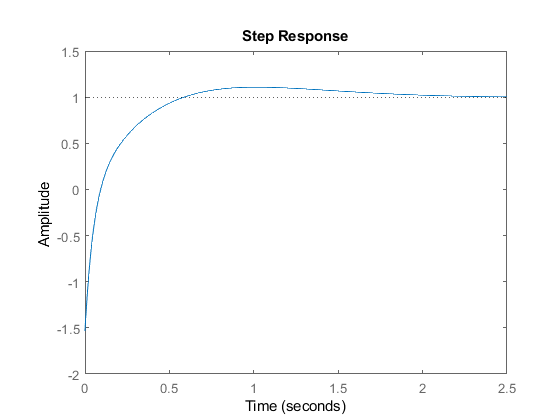

[num,den] = numden(Hc);
num_coeffs = sym2poly(num);
den_coeffs = sym2poly(den);
sys = tf(num_coeffs, den_coeffs);
step(sys)

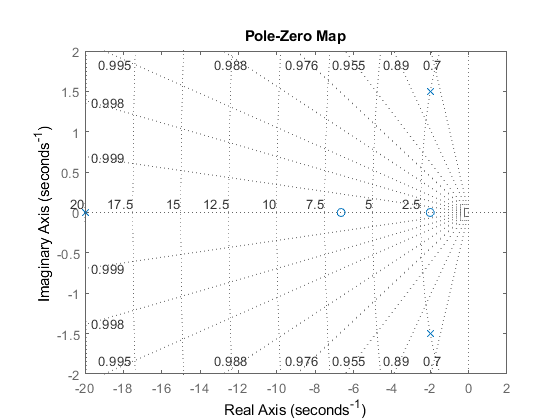

pzmap(sys)
hold on
grid on
xlim([-20, 2])
hold off

stepinfo(sys)

ans = struct with fields:
        RiseTime: 0.3317
    SettlingTime: 1.6493
     SettlingMin: 0.7480
     SettlingMax: 1.1078
       Overshoot: 10.7799
      Undershoot: 153.1250
            Peak: 1.5313
        PeakTime: 0


Perturbación

Hd = simplify(expand( (P) / (1 + C*P)))

$$Hd = \frac{3285750355791570608679454708334592\,s\,\left(s+2\right)}{649037107316853451549808662885421\,s^{3}+15576890575604483557098426336700506\,s^{2}+55979450506078611721174301760552960\,s+81129638414606681695789005144064000}$$

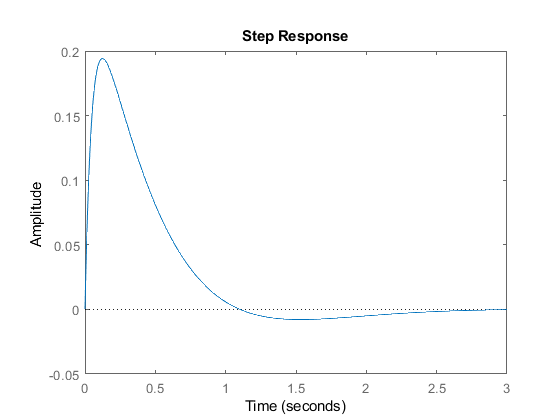

[numd,dend] = numden(Hd);
num_coeffs_d = sym2poly(numd);
den_coeffs_d = sym2poly(dend);
sys_d = tf(num_coeffs_d, den_coeffs_d);
step(sys_d)